pof= @(x) 1./(1+25*x.^2);
x=linspace(-1,1,100);
a1 = linspace(-1,1,10);
a2 = linspace(-1,1,20);
a3 = linspace(-1,1,30);
a4 = linspace(-1,1,40);
b1= f(a1);
b2= f(a2);
b3= f(a3);
b4= f(a4);


A

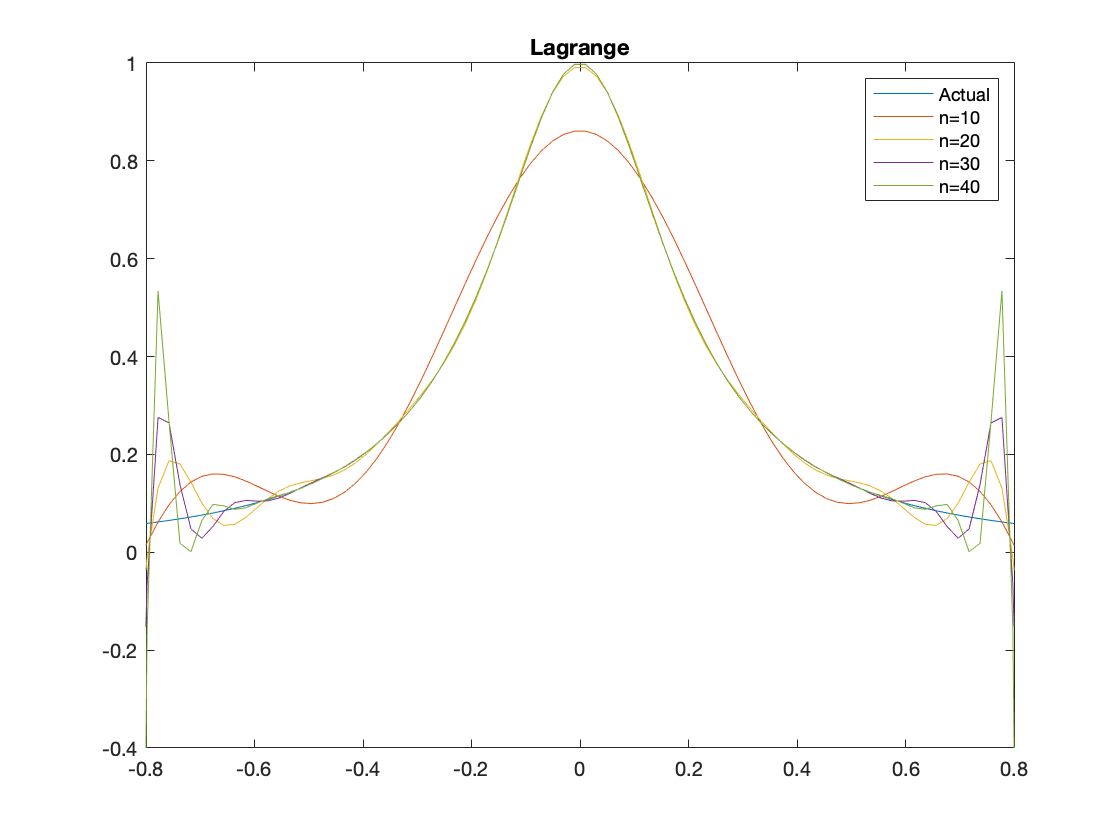

a=linterp(a1,b1,x);
b=linterp(a2,b2,x);
c=linterp(a3,b3,x);
d=linterp(a4,b4,x);
plot(x,f(x),x,a,x,b,x,c,x,d);xlim([-.8,.8])
legend('Actual','n=10','n=20','n=30','n=40')
title('Lagrange')

%no

B

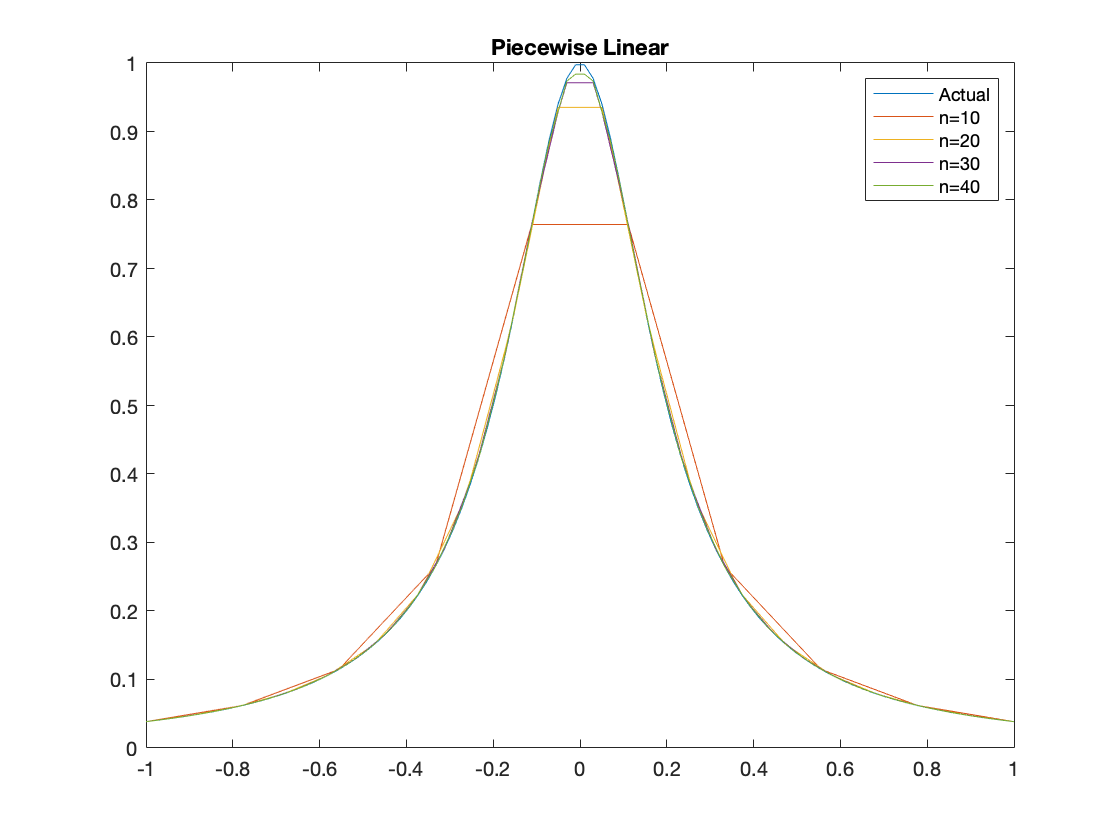

a=polyinterp(a1,b1,x);
b=polyinterp(a2,b2,x);
c=polyinterp(a3,b3,x);
d=polyinterp(a4,b4,x);
plot(x,f(x),x,a,x,b,x,c,x,d)
legend('Actual','n=10','n=20','n=30','n=40')
title('Piecewise Linear')

%yes

C

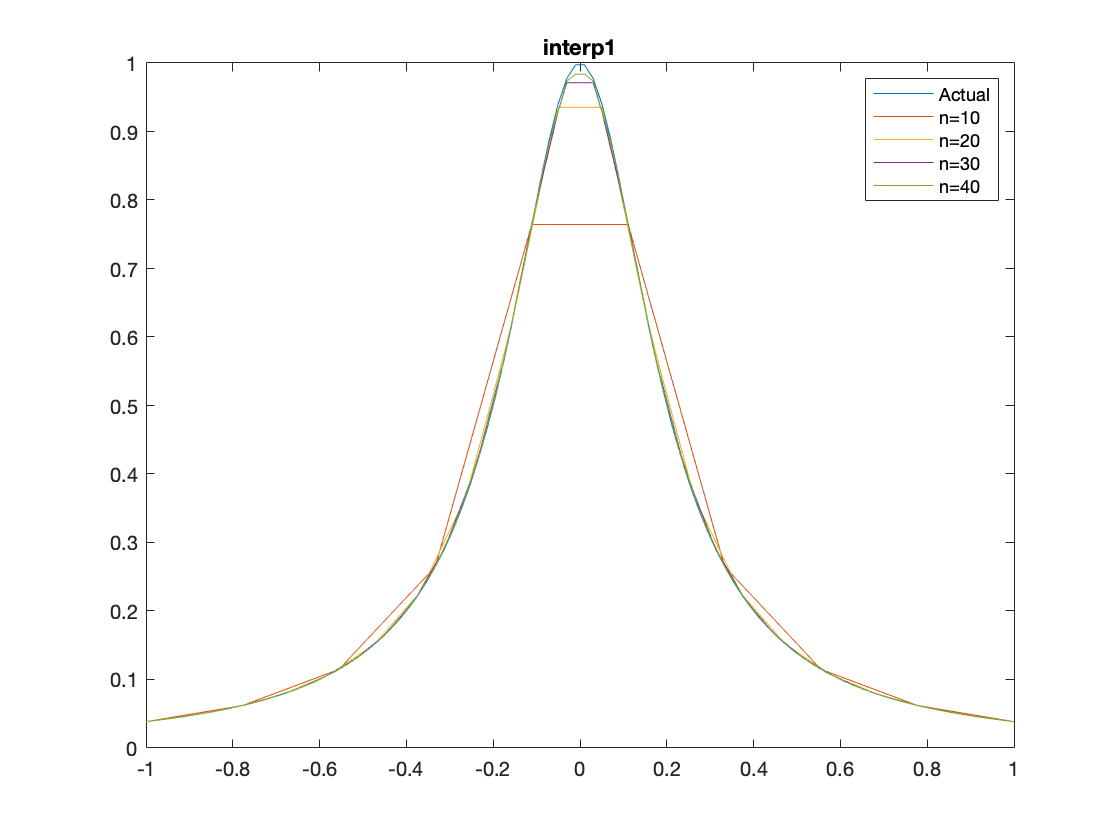

a=interp1(a1,b1,x);
b=interp1(a2,b2,x);
c=interp1(a3,b3,x);
d=interp1(a4,b4,x);
plot(x,f(x),x,a,x,b,x,c,x,d)
legend('Actual','n=10','n=20','n=30','n=40')
title('interp1')

D

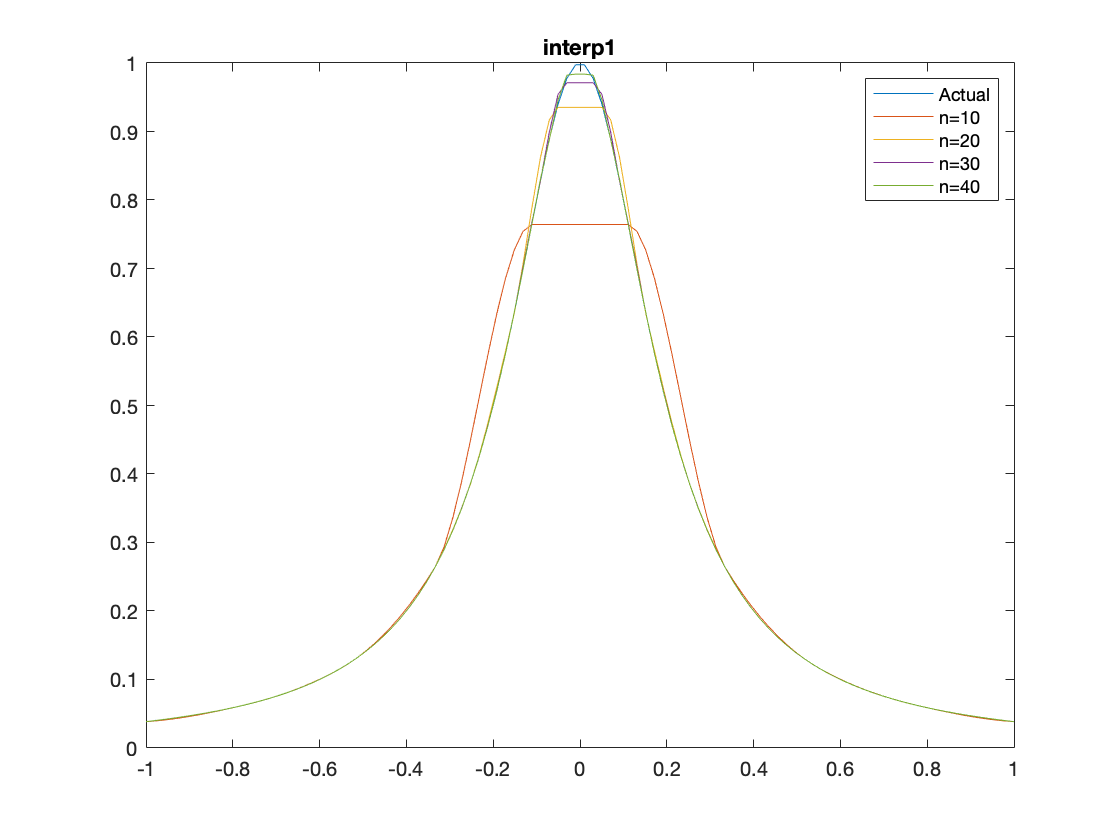

a=interp1(a1,b1,x,'pchip');
b=interp1(a2,b2,x,'pchip');
c=interp1(a3,b3,x,'pchip');
d=interp1(a4,b4,x,'pchip');
plot(x,f(x),x,a,x,b,x,c,x,d)
legend('Actual','n=10','n=20','n=30','n=40')
title('interp1')

%no

function v = polyinterp(X,Y,x)
slope = diff(Y)./diff(X);
k = ones(size(x));
n = length(X);
for j = 2:n-1
    k(X(j) <= x) = j;
end
s = x - X(k);
v = Y(k) + s.*slope(k);
end

function y = linterp(X,Y,x)
n=size(X,2);
L=ones(n,size(x,2));
   for i=1:n
      for j=1:n
         if (i~=j)
            L(i,:)=L(i,:).*(x-X(j))/(X(i)-X(j));
         end
      end
   end
   y=0;
   for i=1:n
      y=y+Y(i)*L(i,:);
   end
end